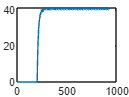

pwm_freq=2000;
Ts=0.005;
velocity;
velocity_mean=mean(velocity.data);
plot(velocity.data);

t=velocity.time;
y=velocity.data;

ss_value = 40.75; % Valore di stato stazionario
u=6;
% Dati del sistema
mu = ss_value / u % Guadagno in continua

mu = 6.7917

%mu=6.7917
% Trova il punto di massima pendenza
[max_slope, max_slope_index] = max(diff(y) ./ diff(t));
theta = t(max_slope_index + 1);



disp('Funzione di trasferimento:');

Funzione di trasferimento:


disp(G);

  tf with properties:

       Numerator: {[0 6.7917]}
     Denominator: {[-0.3364 1]}
        Variable: 's'
         IODelay: 0
      InputDelay: 30.0769
     OutputDelay: 0
       InputName: {''}
       InputUnit: {''}
      InputGroup: [1×1 struct]
      OutputName: {''}
      OutputUnit: {''}
     OutputGroup: [1×1 struct]
           Notes: [0×1 string]
        UserData: []
            Name: ''
              Ts: 0
        TimeUnit: 'seconds'
    SamplingGrid: [1×1 struct]



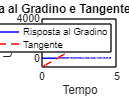


% Plot della risposta al gradino e della tangente sovrapposti
figure;
plot(t, y, 'b'); % Plot della risposta al gradino
hold on;

% Plot della tangente
tangent_slope = max_slope * (t - theta);
plot(t, tangent_slope, 'r--');

title('Risposta al Gradino e Tangente Sovrapposte');
xlabel('Tempo');
ylabel('Uscita');
legend('Risposta al Gradino', 'Tangente');

hold off;


%dal grafico 
tau=1.015

tau = 1.0150

eta=870 %dal grafico

eta = 870

T=tau*ss_value/eta

T = 0.0475


s = tf('s');
G = mu / (1 + T * s) * exp(-tau * s)

G =
 
                     6.792
  exp(-1.01*s) * -------------
                 0.04754 s + 1
 
Continuous-time transfer function.
Model Properties
